# **Elaborato Biomedico**

Il dataset utilizzato in questo progetto è **"Heart Failure Clinical Records"**, una raccolta di dati clinici anonimizzati. La fonte primaria è l'**UCI Machine Learning Repository**, un archivio accademico di fama mondiale gestito dall'Università della California, Irvine, che garantisce l'affidabilità e la qualità dei dati per scopi di ricerca.

- **URL Fonte Primaria:** [https://archive.ics.uci.edu/dataset/519/heart+failure+clinical+records](https://archive.ics.uci.edu/dataset/519/heart+failure+clinical+records)

- **Autori:** Davide Chicco, Giuseppe Jurman (2020)

- **Pubblicazione Scientifica di Riferimento:** *BMC Medical Informatics and Decision Making*

Il file scaricato, `heart_failure_clinical_records_dataset.csv`, è in formato **CSV (Comma-Separated Values)**. Si tratta di un file di testo in cui ogni riga rappresenta un paziente e i valori di ogni colonna (le feature) sono separati da una virgola. Questo formato è universale e facilmente importabile da quasi tutti i software di analisi dati, incluso MATLAB.

**Contenuto e Scopo del Dataset**

Il dataset contiene **299 record clinici** di pazienti affetti da scompenso cardiaco, raccolti durante il loro periodo di follow-up. Lo scopo principale di questa raccolta dati è fornire una base per lo sviluppo di modelli di machine learning in grado di **predire la mortalità** (l'evento di decesso) basandosi su 12 feature cliniche.

Ogni riga corrisponde a un singolo paziente e contiene una combinazione di dati demografici, abitudini e misurazioni di laboratorio.

Il dataset è composto da 13 colonne. 12 sono le **feature** (predittori) e una è la **variabile target** (l'esito da predire).

L'obiettivo di questo progetto è sviluppare e analizzare un sistema interattivo tramite LiveScript per la predizione della mortalità in pazienti affetti da scompenso cardiaco, una delle principali cause di decesso a livello globale.

Per lo sviluppo del progetto ho seguito il seguente approccio:

- Importazione del dataset

- Visualizzazione attraverso dei grafici interattivi di alcune variabili clicniche

- Utilizzo dei modelli predittivi di MATLAB

- Memorizzazione dei risultati su database SQLite

## Inizio LiveScript

% Pulisce l'ambiente di lavoro e la command window
clear; clc;

## Fase 1: Caricamento del file CSV per l'elaborazione

Descrizione Dettagliata dei Campi:

% csvfile = 'heart_failure_clinical_records_dataset.csv';
% Inserisce un controllo di tipo "File Browser" per facilitare l'inserimento del file CSV

csvFile = "D:\Projects\MatLab\Biomedico\heart_failure_clinical_records_dataset.csv";

% Alla funzione loadCSVDataSet viene passato il percorso del file da
% importare nella struttura "dataHeart"

dataHeart = loadCSVDataSet(csvFile, 10);

Il percorso completo del file CSV è il seguente: D:\Projects\MatLab\Biomedico\heart_failure_clinical_records_dataset.csv

Elenco delle prime osservazioni del dataset:

    age    anaemia    creatinine_phosphokinase    diabetes    ejection_fraction    high_blood_pressure    platelets     serum_creatinine    serum_sodium    sex    smoking    time    DEATH_EVENT
    ___    _______    ________________________    ________    _________________    ___________________    __________    ________________    ____________    ___    _______    ____    ___________

 

## Grafico 1: Istogramma della Distribuzione dell'Età

Questo grafico ci mostra come si distribuisce l'età dei pazienti nel dataset. È utile per capire il profilo demografico del campione (es. se i pazienti sono prevalentemente anziani).

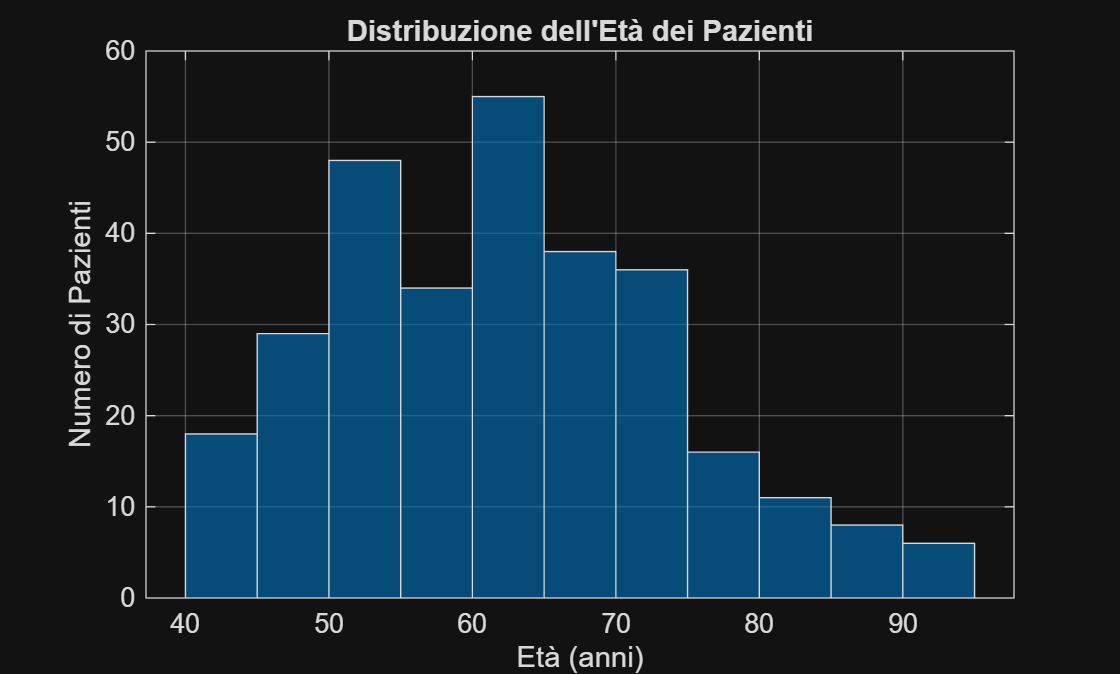

% Inserisce un controllo ti tipo slider per la modifica in realtime dell'istogramma. 

rangeEta = 5;

% Alla funzione plotHistogram viene passato il vettore con i dati relativi all'età

plotHistogram(dataHeart.("age"), rangeEta);

## Grafico 2: Box Plot

Il **Box Plot** (o diagramma a scatola) è uno strumento statistico molto utile per visualizzare la distribuzione di un insieme di dati. Mostra rapidamente la mediana, la dispersione, e la presenza di eventuali outlier.

In particolare:

- **Q1 (primo quartile)**: 25% dei dati sono sotto questo valore (limite inferiore della scatola)

- **Mediana (Q2)**: 50% dei dati sono sotto questo valore (linea centrale nella scatola)

- **Q3 (terzo quartile)**: 75% dei dati sono sotto questo valore (linea superiore della scatola)

- **Whiskers**: si estendono fino ai valori minimi e massimi che non sono outlier (linee dette "whiskers")

- **Outlier**: valori molto distanti dalla media, indicati con "+"

L'utilizzo di questa rappresentazione ci auta nel confronto della distribuzione di tre feature cliniche tra i pazienti sopravvisutti (DEATH_EVENT = 0) e quelli deceduti (DEATH_EVENT = 1).  

Le quattro feature selezionabili sono:

- La frazione di eiezione, ovvero la percentuale di sangue pompata dal ventricolo sinistro ad ogni battito. È il principale indicatore della funzionalità cardiaca. Valori bassi indicano un cuore debole.

- Il livello di creatinina nel siero (mg/dL). È il principale indicatore della funzionalità renale. Un valore alto indica che i reni non funzionano bene, una condizione spesso associata a scompenso cardiaco grave.

- Il livello di sodio nel siero (mEq/L). Valori bassi (iponatriemia) sono un indicatore di prognosi negativa nello scompenso cardiaco.

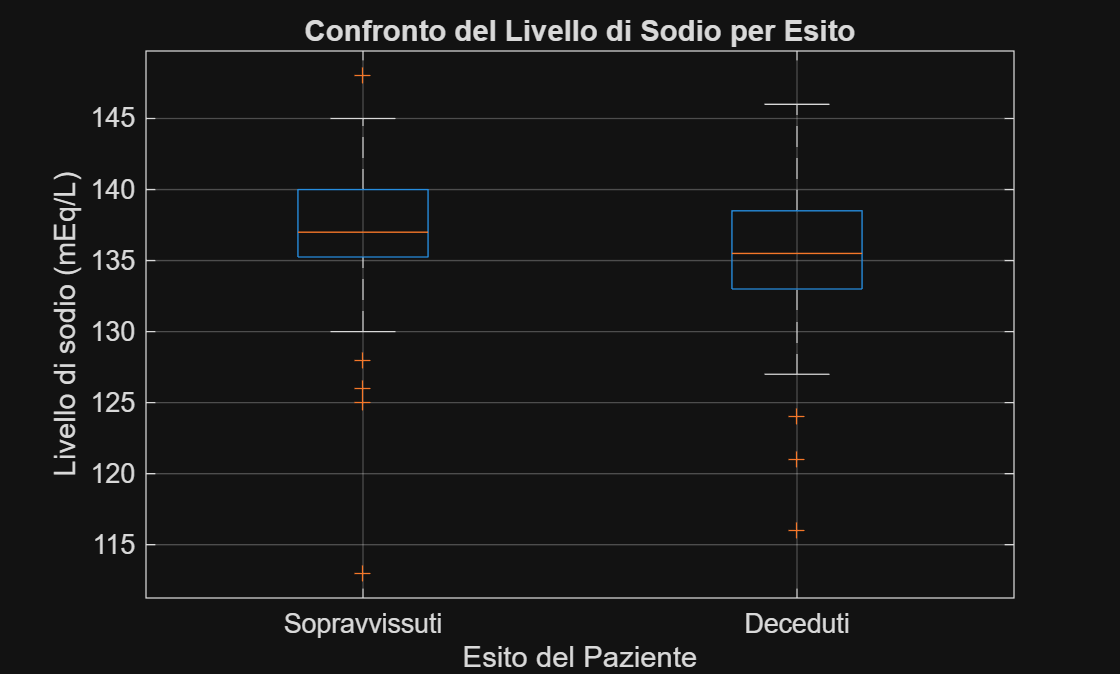

% La lista delle possibili scelte nella casella di controllo di tipo "Drop Down"

boxItems = ["ejection_fraction","serum_creatinine","serum_sodium"];

% Inserisce un controllo di tipo "Drop Down" per la selezione della feature clinica da graficare. 

selectedFeature = boxItems(3);

% ritorna l'indice in corrispondenza della selezione effettuata dall'utente
% e viene passata alla funzione plotBoxPlot_ClinicFeature per impostare il titolo e
% l'etichetta verticale del grafico

selectedIndex = strcmp(boxItems, selectedFeature);

% Alla funzione plotBoxPlot_ClinicFeature viene passato il vettore con i
% dati relativi alla feature "DEATH_EVENT" e il vettore relativo alla "Feature" 
% selezionata dall'utente tramite il controllo "Drop Down" 

plotBoxPlot_ClinicFeature(dataHeart.("DEATH_EVENT"), dataHeart.(selectedFeature), selectedIndex);

## Grafico 3: Scatter Plot - Creatinina vs Sodio Sierico

Lo **scatter plot** (o **grafico a dispersione**) è uno degli strumenti più potenti e intuitivi per la visualizzazione di relazioni tra due variabili quantitative.

In particolare è utile per:

- Individuare **correlazioni** (positive, negative, nulle)

- Rilevare **outlier**

- Visualizzare **cluster** o gruppi di dati

In questa fase, il grafico viene utilizzato per esplorare la relazione tra due importanti biomarcatori: la creatinina sierica (indicatore di funzionalità renale) e il sodio sierico. I punti sono colorati in base all'esito (blu=decesso, rosso=sopravvissuto).

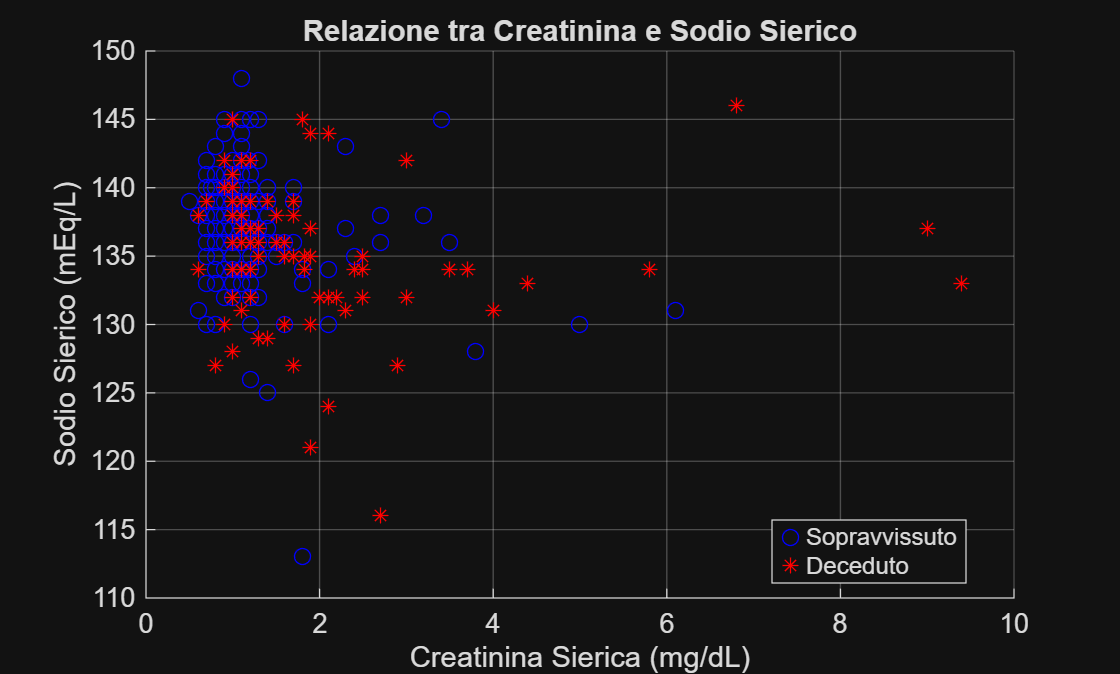

% Alla funzione plotScatter_Creatinina_vs_SodioSierico viene passato il vettore con i
% dati relativi alla feature "serum_creatinine" sulle ascisse e il vettore relativo alla
% feature "serum_sodium" sulle ordinate, la feature "DEATH_EVENT" viene
% utilizzata per colorare i cerchi in base al suo valore (0|1)

plotScatter_Creatinina_vs_SodioSierico(dataHeart.("serum_creatinine"), dataHeart.("serum_sodium"), dataHeart.("DEATH_EVENT"));

## Grafico 4: Matrice di Correlazione (Heatmap)

Il **grafico heatmap** (o mappa di calore) è uno strumento visivo per la rappresentazione di dati bidimensionali, dove i valori sono codificati attraverso variazioni di colore. In altre parole, serve per capire se (e quanto) due variabili sono legate tra loro. 

In tale grafico:

- Ogni cella rappresenta un valore numerico;

- Il **colore** indica l’intensità o la grandezza del valore.

La heatmap visualizza il coefficiente di correlazione di Pearson tra ogni coppia di variabili nel dataset.

- Valori vicini a +1 indicano una forte correlazione positiva (giallo). Dunque, se una variabile cresce, cresce anche l'altra.

- Valori vicini a -1 indicano una forte correlazione negativa (blu). Dunque, se una variabile cresce, l'altra tende a diminuire.

- Valori vicini a 0 indicano assenza di correlazione lineare (colori intermedi).

In questo caso, è particolarmente utile per capire quali variabili cliniche sono più fortemente legate alla variabile 'DEATH_EVENT'.

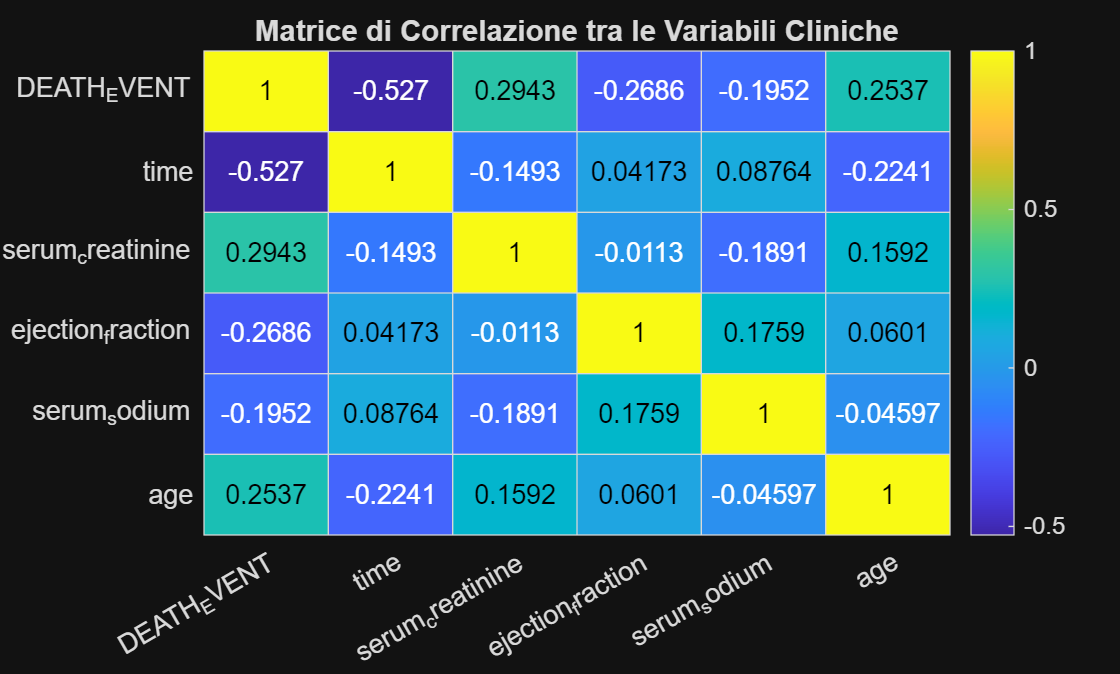

% Alla funzione plotHeatMap viene passato tutta la tabella con le varie feature cliniche 
% in modo da evidenziare le correlazioni

selectedFeature = {'DEATH_EVENT','time', 'serum_creatinine', 'ejection_fraction', 'serum_sodium', 'age'};

selectedDati = dataHeart(:, selectedFeature);

plotHeatMap(selectedDati);

## Implementazione degli Algoritmi di previzione 

### Albero Decisionale (fitctree)

Si tratta di un algoritmo predittivo basato su regole decisionali che, attraverso tecniche di classificazione, organizza i dati in una struttura ad albero.

### **Support Vector Machine (fitcsvm)**

Si tratta di un algoritmo predittivo che separa i dati trovando il confine ottimale (iperpiano), massimizzando il margine tra i punti di classi (feature) diverse. 

#### **Spiegazione della Variabile **`testSetPercentage``:`

La variabile `testSetPercentage` è fondamentale in qualsiasi progetto di machine learning: indica la percentuale del dataset originale che viene **messa da parte e riservata esclusivamente alla valutazione finale del modello**.

#### **Selezione delle Feature** (Predittori):

Dalla heatmap (Grafico 4), osserviamo che le variabili con la più forte correlazione (positiva o negativa) con 'DEATH_EVENT' sono:

- **time**: Correlazione fortemente negativa. Più è lungo il periodo di follow-up, minore è la probabilità di decesso registrata.

- **serum_creatinine**: Correlazione positiva. Livelli alti sono un forte predittore di mortalità.

- **ejection_fraction**: Correlazione negativa. Una bassa frazione di predittore di mortalità.

- **age**: Correlazione positiva. L'età avanzata aumenta il rischio.

Dunque, selezioniamo queste quattro feature come predittori per il nostro modello.

Addestramento del modello (Support Vector Machine (SVM)) in corso...
Addestramento completato in 0.010 secondi.
Valutazione del modello sul test set...
-> Accuratezza del modello: 84.75%
-> Pazienti sopravvissuti che il modello ha erroneamente predetto come deceduti (Falsi Positivi): 6
-> Pazienti deceduti che il modello ha erroneamente predetto come sopravvissuti (Falsi Negativi): 3 (ERRORE PIÙ GRAVE)


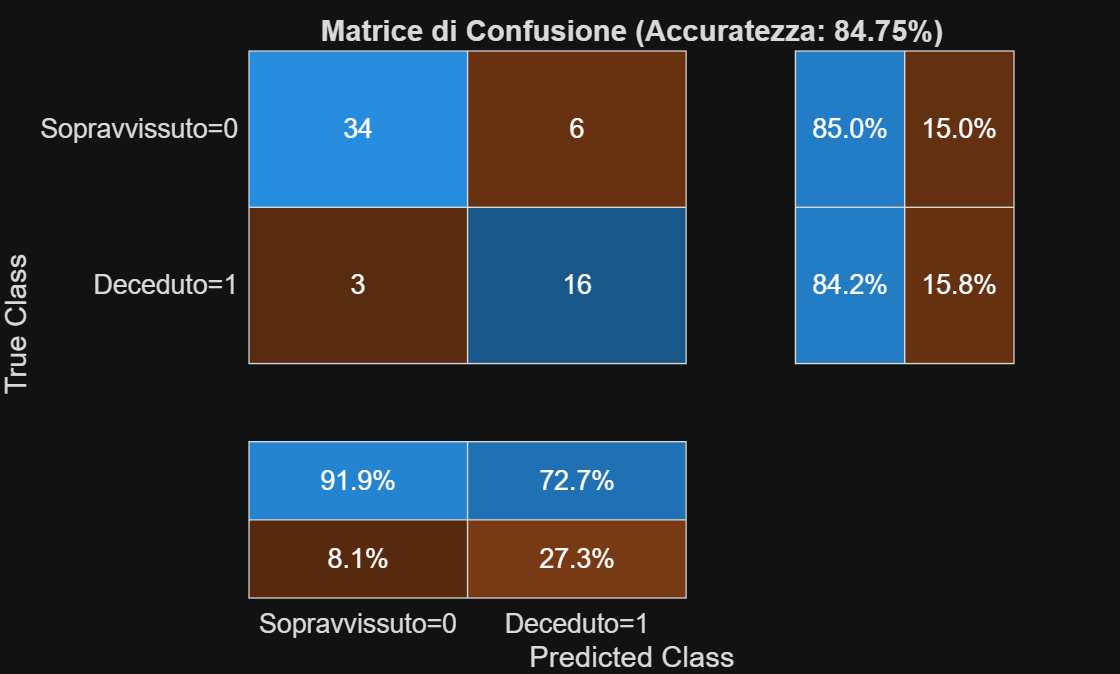

% Suddivisione in Training 80% e Test Set 20%

testSetPercentage = 20;

% Seleziona le feature più interessanti...
predictors = dataHeart(:, {'time', 'serum_creatinine', 'ejection_fraction', 'age'});

% La variabile target
response = dataHeart.('DEATH_EVENT');

% Scelta da parte dell'utente quale modello vuole usare:
% - Albero Decisionale
% - Support Vector Machine (SVM)
% Entrambi sono algoritmi implementati in MatLab

modelID = 1;

switch modelID
    case 0
        modelSelection = "Albero Decisionale";
    case 1
        modelSelection = "Support Vector Machine (SVM)";
end

modelResult = plotModel(predictors, response, modelSelection, testSetPercentage/100);

## Inserimento dei risultati in un DB SQLite

SQLite è un database serverless basato su un singolo file, pertanto non richiede un server separato e può essere facilmente creato, gestito e distribuito insieme al LiveScript di MATLAB.

Lo scopo di questo database non è quello di duplicare i dati clinici originali, ma di "tenere traccia" degli esperimenti di machine learning condotti attraverso il LiveScript. Ogni volta che lo script viene eseguito con parametri diversi (es. un modello diverso, una diversa percentuale di test set), i risultati vengono salvati automaticamente. Ciò, permette di tracciare, confrontare e analizzare le performance nel tempo.

L'architettura è basata su un modello relazionale semplice (`esperimenti_cuore.db`) che contiene quattro tabelle.

### **Dettaglio delle entità**

### Struttura del Diagramma ER

Ecco una rappresentazione testuale del diagramma:

`[Modello] <1-∞> [Esperimento] <1-∞> [Parametro]`

`                      |1`

`                      ∨`

`                 [Risultato]`

### **Relazioni**

- Ogni **Esperimento** è associato a un **Modello** → relazione *molti-a-uno*

- Ogni **Parametro** è associato a un **Esperimento** → relazione *molti-a-uno*

- Ogni **Risultato** è associato a un **Esperimento** → relazione *uno-a-uno* (grazie al vincolo `UNIQUE`)

### **Codice SQL (DDL)**

Il seguente codice SQL viene utilizzato per creare la struttura del database.

`CREATE TABLE IF NOT EXISTS Modelli (`

`    id_modello INTEGER PRIMARY KEY AUTOINCREMENT, `

`    nome_modello TEXT NOT NULL UNIQUE, `

`    descrizione TEXT`

`);`

`CREATE TABLE IF NOT EXISTS Esperimenti (`

`    id_esperimento INTEGER PRIMARY KEY AUTOINCREMENT, `

`    fk_id_modello INTEGER NOT NULL, `

`    data_esecuzione DATETIME NOT NULL, `

`    descrizione TEXT, `

`    FOREIGN KEY (fk_id_modello) REFERENCES Modelli (id_modello)`

`);`

`CREATE TABLE IF NOT EXISTS Parametri (`

`    id_parametro INTEGER PRIMARY KEY AUTOINCREMENT, `

`    fk_id_esperimento INTEGER NOT NULL, `

`    nome_parametro TEXT NOT NULL, `

`    valore_parametro TEXT NOT NULL, `

`    FOREIGN KEY (fk_id_esperimento) REFERENCES Esperimenti (id_esperimento)`

`);`

`CREATE TABLE IF NOT EXISTS Risultati (`

`    id_risultato INTEGER PRIMARY KEY AUTOINCREMENT, `

`    fk_id_esperimento INTEGER NOT NULL UNIQUE, `

`    accuratezza REAL, `

`    falsi_positivi INTEGER, `

`    falsi_negativi INTEGER, `

`    veri_positivi INTEGER, `

`    veri_negativi INTEGER, `

`    FOREIGN KEY (fk_id_esperimento) REFERENCES Esperimenti (id_esperimento)`

`);`

% Nome del file del database

dbfile = 'esperimenti_cuore.db';

% Controllo se il file esiste e imposto la modalità di accesso
% La funzione exist ritorna 0 se il file non esiste o 2 se il file esiste

if exist(dbfile, 'file') == 2
    mode = 'connect'; % il file esiste, pertanto la modalità sara 'connect'
else
    mode = 'create';  % il file non esiste, pertanto sarà creato un database vuoto con la modalità "create"
end

% Creo la connessione al database SQLite
conn = sqlite(dbfile, mode);

% Creazione delle tabelle e inserimento dei modelli di previsione (se necessario)

if ~CreateTable_and_InsertModelli(conn)

    % Termina l'esecuzione del LiveScript (istruzione return) in caso di errore

    fprintf('LiveScript terminato con errore!');
    return
end

% Inserisco nella tabella i dati relativi all'esperimento appena concluso
modelID = fetch(conn, sprintf("SELECT id_modello FROM Modelli WHERE nome_modello = '%s'", modelSelection));
descrizioneEsperimento = sprintf("Test con %s", modelSelection);
sqlInsertEsperimento = sprintf("INSERT INTO Esperimenti (fk_id_modello, data_esecuzione, descrizione) VALUES (%d, datetime('now'), '%s')", modelID.id_modello, descrizioneEsperimento);
exec(conn, sqlInsertEsperimento);

% Utilizzo la funzione SQl last_insert_rowid() per determinare l'ultimo indice inserito
lastExpID = fetch(conn, "SELECT last_insert_rowid() as lastID");

% Inserimento dei dati relativi ai parametri utilizzati    
sqlInsertParam = sprintf("INSERT INTO Parametri (fk_id_esperimento, nome_parametro, valore_parametro) VALUES (%d, 'percentuale_test_set', '%.1f')", lastExpID.lastID, testSetPercentage);
exec(conn, sqlInsertParam);
    
% Inserimento dei dati relativi ai risultati ottenuti
sqlInsertRisultati = sprintf("INSERT INTO Risultati (fk_id_esperimento, accuratezza, falsi_positivi, falsi_negativi, veri_positivi, veri_negativi) VALUES (%d, %.4f, %d, %d, %d, %d)", ...
    lastExpID.lastID, modelResult.accuracy, modelResult.falsiPositivi, modelResult.falsiNegativi, modelResult.veriPositivi, modelResult.veriNegativi);
exec(conn, sqlInsertRisultati);

fprintf('Risultati salvati con successo nel database degli esperimenti.');

Risultati salvati con successo nel database degli esperimenti.


% Chiusura del db SQLite
close(conn);

% Visualizzazione dello storico degli esperimenti estratti dal database

modelID = 2;

switch modelID
    case 0
        modelSelection = "Albero Decisionale";
    case 1
        modelSelection = "Support Vector Machine (SVM)";
    otherwise
        modelSelection = "%";
end
historicalData = loadResultsFromDB(dbfile, modelSelection);

Recupero dello storico degli esperimenti dal database...
Query di select:
-> 'esperimenti_cuore.db'
-> 'SELECT Esperimenti.id_esperimento, Esperimenti.data_esecuzione, Modelli.nome_modello, Risultati.accuratezza, Risultati.falsi_positivi, Risultati.falsi_negativi, Risultati.veri_positivi, Risultati.veri_negativi FROM Esperimenti LEFT JOIN Modelli ON Esperimenti.fk_id_modello = Modelli.id_modello LEFT JOIN Risultati ON Esperimenti.id_esperimento = Risultati.fk_id_esperimento WHERE Modelli.nome_modello like '%' ORDER BY Esperimenti.data_esecuzione DESC;'

if ~isempty(historicalData)
    fprintf('');
    fprintf('Storico di tutti gli esperimenti salvati:\nModello Selezionato:-> %s\n', modelSelection);
    fprintf('Numero di esperimenti eseguiti:-> %d', size(historicalData,1));
    disp(historicalData);
end

Storico di tutti gli esperimenti salvati:
Modello Selezionato:-> %


Numero di esperimenti eseguiti:-> 4

    id_esperimento       data_esecuzione                nome_modello             accuratezza    falsi_positivi    falsi_negativi    veri_positivi    veri_negativi
    ______________    _____________________    ______________________________    ___________    ______________    ______________    _____________    _____________

          46          "2025-09-03 12:52:21"    "Support Vector Machine (SVM)"      0.8475             6                 3                34               16      
          45          "2025-09-03 12:52:14"    "Support Vector Machine (SVM)"      0.8644             3                 5                37               14      
          44          "2025-09-03 12:52:05"    "Albero Decisionale"        

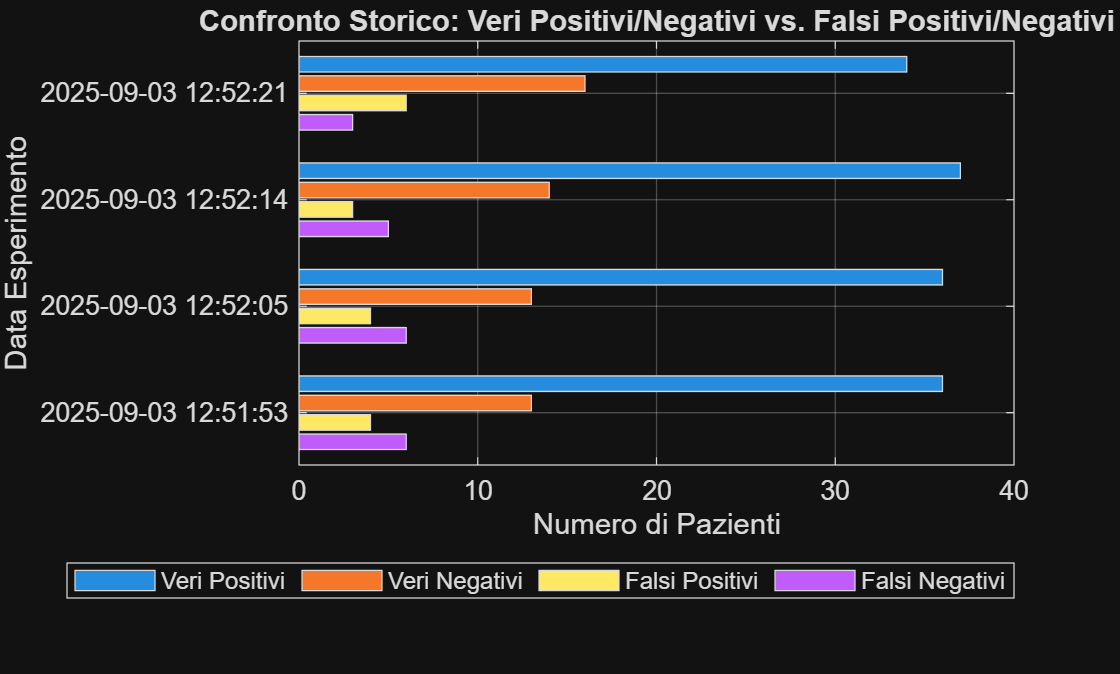

% Grafico a barre verticali
plotHistoricalPerformance(historicalData)


disp('Analisi completata.');

Analisi completata.


% Svuota il database con gli esperimenti, utilizzo di un "Check Box" per
% svuotare la tabella Esperimenti e in cascata tutte le tabelle connesse tramite
% FOREIGN KEY
emptydb = logical(false);
if emptydb
    deleteHistoricalData(dbfile, 'Esperimenti');
end

## Fine LiveScript

## Dichiarazione delle Funzioni del LiveScript

In questa sezione sono implementate tutte le funzioni utilizzate nel LiveScript

- **function** result = loadCSVDataSet(csvFile, nRighe)

- **function** plotHistogram(dataAge, binWidth)

- **function** plotBoxPlot_ClinicFeature(dataX, dataY, idx)

- **function** plotScatter_Creatinina_vs_SodioSierico(dataX, dataY, dataGroup)

- **function** plotHeatMap(dataXY)

- **function** [results] = plotModel(predictors, response, modelType, testSetPercentage)

- **function** result = CreateTable_and_InsertModelli(conn)

- **function** historicalData = loadResultsFromDB(dbfile)

function result = loadCSVDataSet(csvFile, nRighe)
    % Visualizza il percorso del file CSV appena inserito
    fprintf('Il percorso completo del file CSV è il seguente: %s\n', csvFile);

    % Eventuali istruzioni per cambiare il nome dei campi con la traduzione in inglese
    % dati.Properties.VariableNames =  ["Età","Anemia","Creatinina","Diabete","ScompensoCardiaco","PressioneAlta","platelets","serum_creatinine","serum_sodium","sex","smoking","time","death_event"];

    % Il blocco try catch viene utilizzato per gestire eventuali eccezioni durante l'accesso al file
    if isfile(csvFile) % controlla che il file esista
        try
            result = readtable(csvFile);  % legge il file
        
            % Visualizza le righe della tabella per un'anteprima dei dati
            fprintf('\nElenco delle prime osservazioni del dataset:\n\n')
            head(result, nRighe);
        catch exception
            fprintf('Errore durante il caricamento dei dati: %s\n', exception.message);
        end
    end
end

function plotHistogram(dataAge, binWidth)
    % Grafico 1: Istogramma della Distribuzione dell'Età

    % Usa la funzione histogram per visualizzare il grafico
    figure();
    histogram(dataAge, 'BinWidth', binWidth, 'FaceColor', '#0072BD');
    title('Distribuzione dell''Età dei Pazienti');
    xlabel('Età (anni)');
    ylabel('Numero di Pazienti');
    grid on;    
end

function plotBoxPlot_ClinicFeature(dataX, dataY, idx)
    % Grafico 2: Box Plot relativo a diverse Feature clicniche scelte dall'utente
    
    Titles = {'Confronto della Frazione di Eiezione per Esito','Confronto del Livello di Creatinina per Esito','Confronto del Livello di Sodio per Esito'};
    yLabels = {'Frazione di Eiezione (%)','Livello di creatinina (mg/dL)','Livello di sodio (mEq/L)'};
    
    % Usa la funzione boxplot per visualizzare il grafico
    figure();
    boxplot(dataY, dataX, 'Labels', {'Sopravvissuti', 'Deceduti'});
    title(Titles(idx));
    xlabel('Esito del Paziente');
    ylabel(yLabels(idx));
    grid on;
end

function plotScatter_Creatinina_vs_SodioSierico(dataX, dataY, dataGroup)
    % Grafico 2: Box Plot relativo a diverse Feature clicniche scelte dall'utente
    
    % Usa la funzione heatmap per visualizzare il grafico
    figure();
    gscatter(dataX, dataY, dataGroup, 'br', 'o*');
    title('Relazione tra Creatinina e Sodio Sierico');
    xlabel('Creatinina Sierica (mg/dL)');
    ylabel('Sodio Sierico (mEq/L)');
    legend('Sopravvissuto', 'Deceduto', 'Location', 'best');
    grid on;
end

function plotHeatMap(dataXY)
    % Grafico 3: Heat Plot relativo a diverse Feature cliniche per valutare le correlazioni

    % Calcola la matrice di correlazione
    corrMatrix = corrcoef(table2array(dataXY));
    
    % Usa la funzione heatmap per visualizzare il grafico
    figure();  
    heatmap(dataXY.Properties.VariableNames, dataXY.Properties.VariableNames, corrMatrix,"Colormap", parula);
    title('Matrice di Correlazione tra le Variabili Cliniche');
end

function results = plotModel(predictors, response, modelType, testSetPercentage)
    % Funzione per addestrare e valutare il modello di classificazione

    % Togliamo dal dataset la percentuale stabilita dall'utente
    cv = cvpartition(response, 'HoldOut', testSetPercentage);
    idxTrain = training(cv);
    idxTest = test(cv);

    % Creo le tabelle per training e test
    XTrain = predictors(idxTrain,:);
    YTrain = response(idxTrain,:);
    XTest = predictors(idxTest,:);
    YTest = response(idxTest,:);

    fprintf('Addestramento del modello (%s) in corso...\n', modelType);
    
    % Avvio il cronometro per misurare il tempo di addestramento
    tic;

    % In base al modello scelto dall'utente avvio la relativa funzione MatLab per il training 
    switch modelType
        case "Albero Decisionale"
            trainedModel = fitctree(XTrain, YTrain);
        case "Support Vector Machine (SVM)"
            trainedModel = fitcsvm(XTrain, YTrain, 'Standardize', true);
    end

    % Fermo il cronometro
    trainingTime = toc;
    fprintf('Addestramento completato in %.3f secondi.\n', trainingTime);
    
    % Valutazione del Modello
    % Usiamo il modello addestrato per fare previsioni sul test set.
    fprintf('Valutazione del modello sul test set...\n');
    
    YPred = predict(trainedModel, XTest);

    % Calcoliamo l'accuratezza complessiva
    accuracy = sum(YPred == YTest) / numel(YTest);
    fprintf('-> Accuratezza del modello: %.2f%%\n', accuracy * 100);   

    % Costruisco una struttura dati con i valori di output del modello di previsione scelto, per poi memorizzarli nella tabella sql dei risultati
    cm = confusionmat(YTest, YPred);
    results.falsiPositivi = cm(1,2);
    results.falsiNegativi = cm(2,1);
    results.veriPositivi = cm(1,1);
    results.veriNegativi = cm(2,2);
    results.accuracy = accuracy;

    % Stampo i risultati con una spiegazione
    fprintf('-> Pazienti sopravvissuti che il modello ha erroneamente predetto come deceduti (Falsi Positivi): %d\n', results.falsiPositivi);
    fprintf('-> Pazienti deceduti che il modello ha erroneamente predetto come sopravvissuti (Falsi Negativi): %d (ERRORE PIÙ GRAVE)\n', results.falsiNegativi);    

    % Visualizzo la matrice di confusione per un'analisi dettagliata dei risultati
    figure();
    YTestCat = categorical(YTest,[0 1],{'Sopravvissuto=0','Deceduto=1'});
    YPredCat = categorical(YPred,[0 1],{'Sopravvissuto=0','Deceduto=1'});
    confusionchart(YTestCat,YPredCat,'RowSummary','row-normalized','ColumnSummary','column-normalized');
    title(sprintf('Matrice di Confusione (Accuratezza: %.2f%%)', accuracy * 100));
end

function result = CreateTable_and_InsertModelli(conn)
    % Funzione per inizializzare il database con le tabelle per gli esperimenti

    tableModelli = 'Modelli';
    tableEsperimenti = 'Esperimenti';
    tableParametri = 'Parametri';
    tableRisultati = 'Risultati';
    
    sqlCreateModelli = sprintf(...
        "CREATE TABLE IF NOT EXISTS %s (" + ...
            "id_modello INTEGER PRIMARY KEY AUTOINCREMENT, " + ...
            "nome_modello TEXT NOT NULL UNIQUE, " + ...
            "descrizione TEXT" + ...
        ");", tableModelli);
    
    sqlCreateEsperimenti = sprintf(...
        "CREATE TABLE IF NOT EXISTS %s (" + ...
            "id_esperimento INTEGER PRIMARY KEY AUTOINCREMENT, " + ...
            "fk_id_modello INTEGER NOT NULL, " + ...
            "data_esecuzione DATETIME NOT NULL, " + ...
            "descrizione TEXT, " + ...
            "FOREIGN KEY (fk_id_modello) REFERENCES %s (id_modello)" + ...
        ");", tableEsperimenti, tableModelli);
    
    sqlCreateParametri = sprintf(...
        "CREATE TABLE IF NOT EXISTS %s (" + ...
            "id_parametro INTEGER PRIMARY KEY AUTOINCREMENT, " + ...
            "fk_id_esperimento INTEGER NOT NULL, " + ...
            "nome_parametro TEXT NOT NULL, " + ...
            "valore_parametro TEXT NOT NULL, " + ...
            "FOREIGN KEY (fk_id_esperimento) REFERENCES %s (id_esperimento)" + ...
        ");", tableParametri, tableEsperimenti);
    
    sqlCreateRisultati = sprintf(...
        "CREATE TABLE IF NOT EXISTS %s (" + ...
            "id_risultato INTEGER PRIMARY KEY AUTOINCREMENT, " + ...
            "fk_id_esperimento INTEGER NOT NULL UNIQUE, " + ...
            "accuratezza REAL, " + ...
            "falsi_positivi INTEGER, " + ...
            "falsi_negativi INTEGER, " + ...
            "veri_positivi INTEGER, " + ...
            "veri_negativi INTEGER, " + ...
            "FOREIGN KEY (fk_id_esperimento) REFERENCES %s (id_esperimento)" + ...
        ");", tableRisultati, tableEsperimenti);
    
    % Query di inserimento per i due modelli di previsione 
    sqlInsertModelli = "INSERT OR IGNORE INTO %s (nome_modello) VALUES ('%s');";
    
    try
        execute(conn, sqlCreateModelli);
        execute(conn, sqlCreateEsperimenti);
        execute(conn, sqlCreateParametri);
        execute(conn, sqlCreateRisultati);

        % Inserisce i due modelli di default trattati

        execute(conn, sprintf(sqlInsertModelli, tableModelli, "Albero Decisionale"));
        execute(conn, sprintf(sqlInsertModelli, tableModelli, "Support Vector Machine (SVM)"));
        result = true;
    catch exception
        fprintf("Errore durante l'inizializzazione del database:\n-> '%s'\n-> '%s'", conn.Database, exception.message);
        result = false;
    end
end

function historicalData = loadResultsFromDB(dbfile, modelSelected)
    % Funzione per caricare lo storico dal database degli esperimenti

    fprintf('Recupero dello storico degli esperimenti dal database...\n');
    historicalData = table();
    if isfile(dbfile)
        try
            conn = sqlite(dbfile, 'readonly');
            % Query con LEFT JOIN per unire le informazioni rilevanti
            %                 

            sqlSelect = sprintf(...
                "SELECT " + ...
                    "Esperimenti.id_esperimento, " + ...
                    "Esperimenti.data_esecuzione, " + ...
                    "Modelli.nome_modello, " + ...
                    "Risultati.accuratezza, " + ...
                    "Risultati.falsi_positivi, " + ...
                    "Risultati.falsi_negativi, " + ...
                    "Risultati.veri_positivi, " + ...
                    "Risultati.veri_negativi " + ...
                "FROM " + ...
                    "Esperimenti " + ...
                "LEFT JOIN " + ...
                    "Modelli ON Esperimenti.fk_id_modello = Modelli.id_modello " + ...
                "LEFT JOIN " + ...
                    "Risultati ON Esperimenti.id_esperimento = Risultati.fk_id_esperimento " + ...
                "WHERE Modelli.nome_modello like '%s' " + ...
                "ORDER BY " + ...
                    "Esperimenti.data_esecuzione DESC;", modelSelected);
            fprintf("Query di select:\n-> '%s'\n-> '%s'", conn.Database, sqlSelect);
            historicalData = fetch(conn, sqlSelect);
            close(conn);
        catch exception
            fprintf("ERRORE: impossibile leggere i dati dal database:\n-> '%s'\n-> '%s'", conn.Database, exception.message);
            close(conn);
        end
    else
        fprintf('File del database non ancora creato.');
    end
end

function deleteHistoricalData(dbfile, tableName)
    % Funzione per la cancellazione di tutti gli esperimenti
    if isfile(dbfile)
        try
            conn = sqlite(dbfile, 'connect');
            sqlDelete = sprintf("DELETE FROM %s", tableName);
            execute(conn, sqlDelete);
            fprintf("Database Esperimenti svuotato con successo.");
        catch exception
            fprintf("ERRORE: impossibile leggere i dati dal database:\n-> '%s'\n-> '%s'", conn.Database, exception.message);
            close(conn);
        end
    end
end

function plotHistoricalPerformance(data)
    % Confronto Performance Storiche (Orizzontale)
    figure('Name', 'Confronto Performance Storiche degli Esperimenti');
    
    yData = [data.veri_positivi, data.veri_negativi, data.falsi_positivi, data.falsi_negativi];
    
    % Visualizza il grafico a barre orizzontale
    barh(yData, 'grouped');
    
    % Mostra l'esperimento più recente in alto
    set(gca, 'YDir','reverse');
    
    title('Confronto Storico: Veri Positivi/Negativi vs. Falsi Positivi/Negativi');
    xlabel('Numero di Pazienti'); % L'etichetta X rappresenta il conteggio
    ylabel('Data Esperimento'); % L'etichetta Y rappresenta le categorie e si è scelto la data dell'esperimento
    
    % Etichette per l'asse Y
    yticks(1:height(data));
    yticklabels(data.data_esecuzione);
    
    legend('Veri Positivi', 'Veri Negativi', 'Falsi Positivi', 'Falsi Negativi', 'Orientation','horizontal','Location','bestoutside');
    grid on;
    
end

